**As always - choose 2 images. **

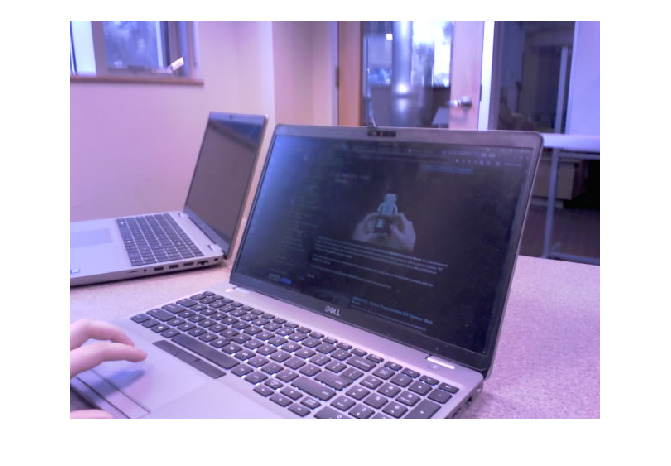

im1 = imread('../images/IMAGE001.jpg');
im2 = imread('../images/IMAGE003.jpg');
imshow(im1)

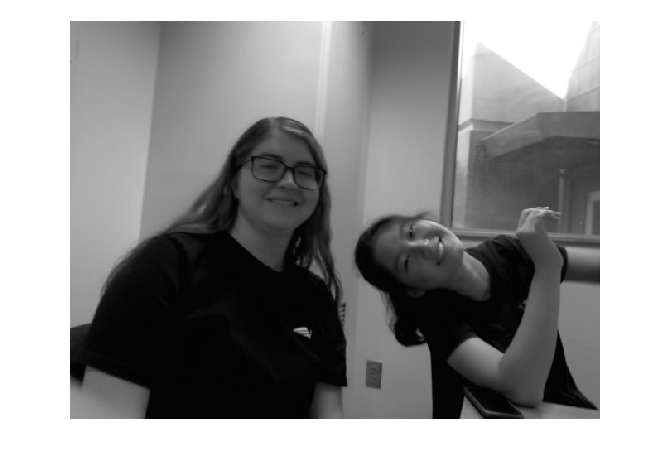

imshow(im2)

**1) Second Order Gradient (total 40 points)**

- Apply Laplace of Gaussian (LoG) to your images to find edges (10)

- Apply Canny edge detector to your images to detect edges (10)

- Comment on how well each of them work on your images (20)

**2) Image Segmentation using clustering (total 30 points)**

- Apply k-means algorithm to your images.(10)

- How many clusters seem to work well for your images? (10)

- What parameters did you use? (e.g. R, G, B, H, S, V....). Did these work well? (10)

- Just for your own learning: Can you apply mean-shift clustering to your images? (0 points)

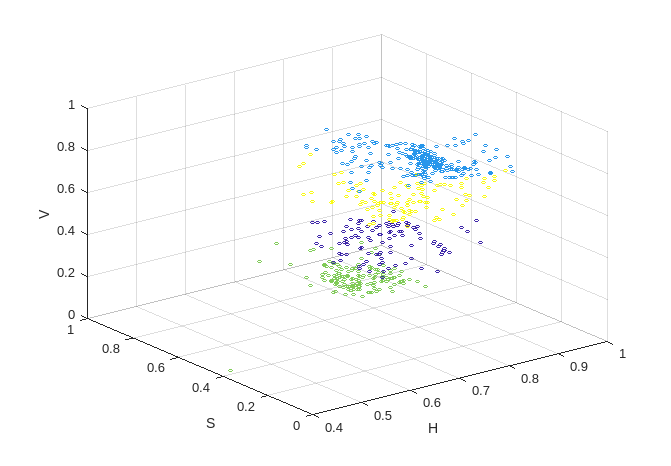

[im1new, h1, s1, v1, p1] = kmeansHSV(im1, 4);
scatter3(h1(1:500:end), s1(1:500:end), v1(1:500:end), 6, p1(1:500:end))
xlabel("H")
ylabel("S")
zlabel("V")

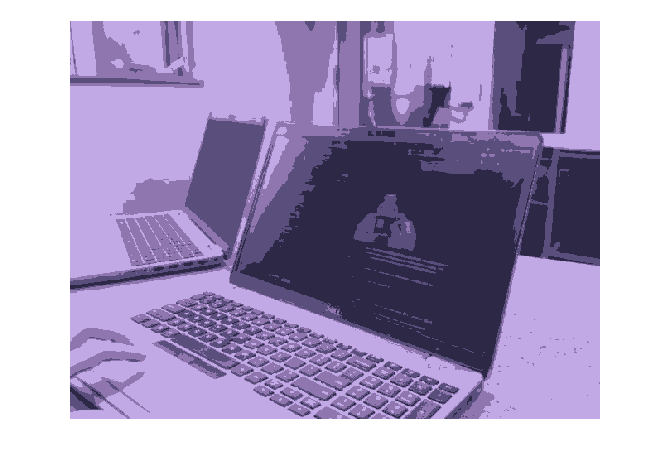

imshow(im1new);

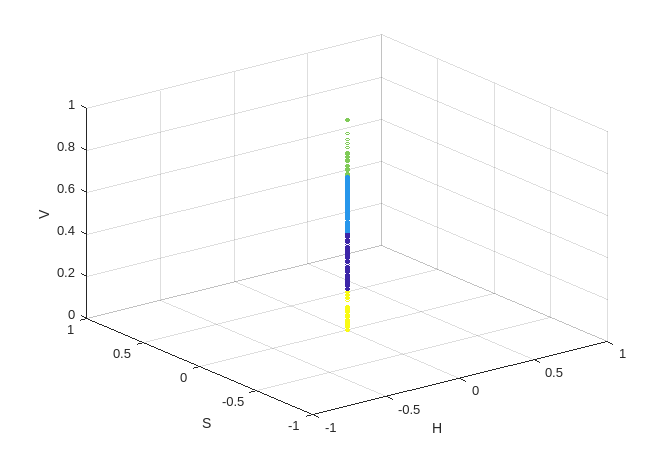

[im2new, h2, s2, v2, p2] = kmeansHSV(im2, 4);
scatter3(h2(1:500:end), s2(1:500:end), v2(1:500:end), 6, p2(1:500:end))
xlabel("H")
ylabel("S")
zlabel("V")

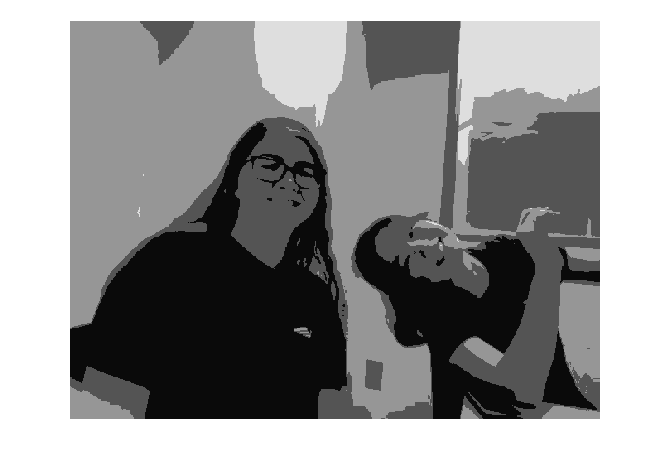

imshow(im2new);

I used HSV as the dimensions with which to find clusters. Looking at the raw scatterplot, there weren't very clear clusters of points Using 4 means worked well in both images. In the first, it is easy to identify the computer screens and keyboards. In the second, the darkest color was reserved for the figures, and it was possible to discern facial features. 

There images were not the most colorful, particularly the gray filtered one. HSV and RGB clustering would likely perform better with more color to discern objects. In this case, it may have been more helpful to use physical distance as a dimension.


function [newimg, h1, s1, v1, p1] = kmeansHSV(img, num)
    hsv1 = rgb2hsv(img);
    h1 = hsv1(:,:,1);
    h1 = reshape(h1.',1,[]);
    s1 = hsv1(:,:,2);
    s1 = reshape(s1.',1,[]);
    v1 = hsv1(:,:,3);
    v1 = reshape(v1.',1,[]);

    mean_idxs = randperm(length(h1), num);
    means = [h1(mean_idxs); s1(mean_idxs); v1(mean_idxs)]';
    p1 = zeros(size(h1));
    
    for i=1:10
        for j=1:length(p1)
            dists = sqrt((means(:,1) - h1(j)).^2 ...
                + (means(:,2) - s1(j)).^2 ...
                + (means(:,3) - v1(j)).^2);
            [maxd, idx] = min(dists);
            p1(j) = idx;
        end 
        for k=1:length(means)
            group = (p1==k);
            sum_h = sum(group.*h1);
            sum_s = sum(group.*s1);
            sum_v = sum(group.*v1);
            means(k,1) = sum_h/sum(group);
            means(k,2) = sum_s/sum(group);
            means(k,3) = sum_v/sum(group);
        end
    end

    h1new = zeros(size(h1));
    s1new = zeros(size(s1));
    v1new = zeros(size(v1));
    for k=1:length(means)
        group = (p1==k);
        h1new = h1new + group.*means(k,1);
        s1new = s1new + group.*means(k,2);
        v1new = v1new + group.*means(k,3);
    end
    
    hsv1new = zeros(size(hsv1));
    for i=1:length(hsv1(:,1))
        for j=1:length(hsv1)
            hsv1new(i,j,1) = h1new( (i-1)*length(hsv1)+j );
            hsv1new(i,j,2) = s1new( (i-1)*length(hsv1)+j );
            hsv1new(i,j,3) = v1new( (i-1)*length(hsv1)+j );
        end
    end
    newimg = hsv2rgb(hsv1new);
end


**3) Corner detection (total 20 points)**

- try out the inbuilt corner detection functions in MATLAB and Python on both your images. (10 points)

- Did you need optimize the "number" of corners to be found for better accuracy? Explain. (10 points)

**4) Hough transform (total 20 points)**

- try out the inbuilt hough transform functions (in MATLAB they are: hough, houghpeaks, houghlines) to detect lines in your image. (20 points)

- What did you need to optimize to find the lines you wanted to find? (10 points)

**5) Applying various concepts together (40 points)**

We have learned many concepts in image processing now. Use a combination of those concepts and methods to find letters in scrabble.jpg. (hint: it is a blurred image, letters have lines, corners, edges, the board has different colors on it).